#### Problem 6

The rotating shaft in the given figure is machined from AISI 1020 CD steel. It is subjected to a force of *F* = 7 kN. Find the minimum factor of safety for fatigue based on infinite life. Be sure to check for yielding.

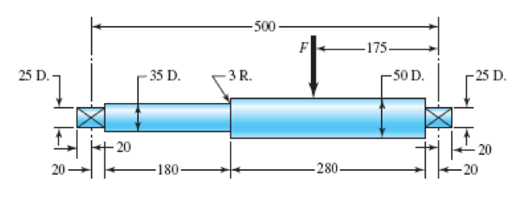

% For AISI 1020 CD, from Table A-20
S_ut = 470; % MPa
S_y = 390; % MPa

F = 7; % kN
r = 3; % mm
D = 50; % mm
d = 35; % mm

% What are the values of the theoretical stress-concentration factor, 
% the notch sensitivity, and the fatigue stress concentration-factor?

% Theoretical stress concentration factor
Dd = D/d;
rd = r/d;

K_t = 1.7

K_t = 1.7000


% Neuber's constant
neuber_bending = 1.24 ...
                 - 2.25*(10^-3)*S_ut ...
                 + 1.60*(10^-6)*S_ut^2 ...
                 - 4.11*(10^-10)*S_ut^3 % mm^(1/2)

neuber_bending = 0.4933


% Notch sensitivity
q = 1/(1 + neuber_bending/sqrt(r))

q = 0.7783


% Fatigue stress concentration factor
K_f = 1 + q*(K_t - 1)

K_f = 1.5448